# Rotary Inverted Pendulum

## Motor Parameters

motor_b = 0.0039055       ;   % Damping Coefficient
motor_j = 0.0003          ;   % System Inertia
motor_km = 0.078249       ;   % Motor speed constant
motor_kt = 0.078249       ;   % Motor Torque constant
motor_l = 0.0054872       ;   % Motor inductance
motor_r = 6               ;   % Motor Resistance
motor_effeciency = 0.69   ;   % Motor effeciency
gear_box_effeciency = 0.9 ;   % Gearbox Effeciency
gear_box_ratio = 46.73    ;   % Motor gearbox ratio



## System Parameters


m_pendulum = 17     ;  %the mass of pendulum in gram
r = 40               ;  %length of arm in mm
l = 65/2           ;  %length of arm of pendulum in mm


## State Space Parameters

a=motor_j+(m_pendulum*r*r);
b=m_pendulum*l*r;
c=(4/3)*m_pendulum*l*l;
d=m_pendulum*9.8*l;

E=(a*c)-(b*b);
G = ((motor_effeciency*gear_box_effeciency*motor_km*motor_kt*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r);

H= (motor_effeciency*gear_box_effeciency*motor_kt*gear_box_ratio)/(motor_r*E);


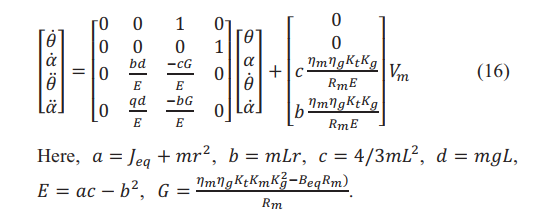

## State Space

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(E) (-(c*G)/E) 0 ; 0 ((a*d)/E) (-b*G)/E 0 ]; % system matrix
B_mat=[0;0;(c)*(H);(b)*(H)];                                                % input matrix  
C_mat=[1 0 0 0 ; 0 1 0 0];                                                  % output matrix
D_mat=[0;0];                                                                % feedforward matrix

state_space_model =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3           0       0.735  -0.0002029           0
   x4           0      0.9046  -0.0001873           0
 
  B = 
              u1
   x1          0
   x2          0
   x3  5.566e-05
   x4  5.137e-05
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



state_space_model=ss(A_mat,B_mat,C_mat,D_mat)                              % State space object


## LQR Parameters

q=diag([   1e-2     600      600         400      ]);
%      [   theta   alpha   thetadot   alphadot    ]
r_eq=1;

k=lqr(state_space_model,q,r_eq);
    
k_theta=k(1)

k_theta = -0.1000

k_alpha=k(2)

k_alpha = 3.5280e+04

k_thetadot=k(3)

k_thetadot = -126.2804

k_alphadot=k(4) 

k_alphadot = 3.7193e+04

K=[k_alpha, k_alphadot, k_theta, k_thetadot]

K = 1.0e+04 *

    3.5280    3.7193   -0.0000   -0.0126


## Step response

LQR_sys=ss(A_mat-B_mat*k,B_mat,C_mat,0)

LQR_sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3  5.566e-06     -1.229   0.006825      -2.07
   x4  5.137e-06    -0.9079     0.0063     -1.911
 
  B = 
              u1
   x1          0
   x2          0
   x3  5.566e-05
   x4  5.137e-05
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


TF = tf(LQR_sys)

TF =
 
  From input to output...
              5.566e-05 s^2 - 1.236e-20 s - 1.259e-05
   1:  -----------------------------------------------------
       s^4 + 1.904 s^3 + 0.9079 s^2 + 0.001544 s + 1.259e-06
 
              5.137e-05 s^2 - 3.507e-23 s + 9.163e-41
   2:  -----------------------------------------------------
       s^4 + 1.904 s^3 + 0.9079 s^2 + 0.001544 s + 1.259e-06
 
Continuous-time transfer function.


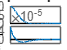

step(TF)